% Heun
clc 
clear
h = 0.1;
x = 0:h:2;
y(1) = 1;


for i = 1:10
    k1(i) = y(i)*x(i).^2 -1.1*y(i);
    y_euler(i) = y(i) + k1(i)*h;
    k2(i) = y_euler(i)*x(i+1).^2 -1.1*y_euler(i);
    phi(i) = (k1(i) + k2(i))/2;
    y(i+1) = y(i) + phi(i)*h;
    y_real(i)=exp((((x(i))^3)/3)-1.1*x(i));
    E=(abs(y_real(i)-y(i))/y_real(i))*100
    disp(y(i))
    plot(x(i),y(i),"*")
    hold on
end

E = 0

     1



E = 0.0404

    0.8965



E = 0.0794

    0.8053



E = 0.1158

    0.7263



E = 0.1484

    0.6589



E = 0.1768

    0.6026



E = 0.2008

    0.5566



E = 0.2206

    0.5202



E = 0.2370

    0.4931



E = 0.2508

    0.4750



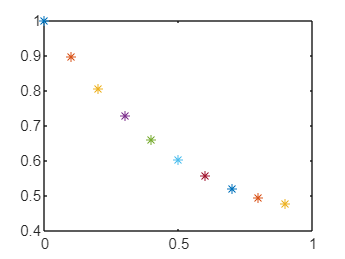

hold off


% Punto Medio
clc 
clear
h = 0.1;
x = 0:h:2;
y(1) = 1;

for i = 1:10
    k1(i) = y(i)*x(i).^2 -1.1*y(i);
    y_euler(i) = y(i) + k1(i)*h*1/2;
    x_half(i)=x(i+1)+1/2*h;
    k2(i) = y_euler(i)*x_half(i)^2 -1.1*y_euler(i);
    phi(i) = (k1(i) + k2(i))/2;
    y(i+1) = y(i) + phi(i)*h;
    y_real(i)=exp((((x(i))^3)/3)-1.1*x(i));
    E=(abs(y_real(i)-y(i))/y_real(i))*100
    disp(y(i))
    plot(x(i),y(i),"*")
    hold on
end

E = 0

     1



E = 0.2282

    0.8941



E = 0.3920

    0.8015



E = 0.4816

    0.7219



E = 0.4881

    0.6547



E = 0.4051

    0.5991



E = 0.2281

    0.5542



E = 0.0438

    0.5193



E = 0.4083

    0.4940



E = 0.8585

    0.4779



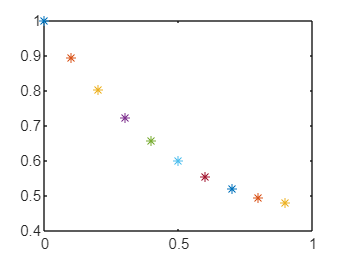

hold off

E = 0

     1



E = 0.1998

    0.8979



E = 0.5380

    0.8090



E = 1.0139

    0.7328



E = 1.6272

    0.6686



E = 2.3781

    0.6158



E = 3.2675

    0.5736



E = 4.2971

    0.5414



E = 5.4688

    0.5189



E = 6.7849

    0.5059



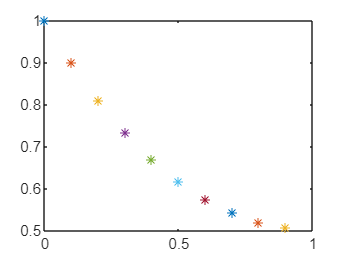



% Raltson
clc 
clear
h = 0.1;
x = 0:h:2;
y(1) = 1;

for i = 1:10
    k1(i) = y(i)*x(i).^2 -1.1*y(i);
    y_euler(i) = y(i) + k1(i)*h*3/4;
    x_quarter(i)=x(i+1)+3/4*h;
    k2(i) = y_euler(i)*x_quarter(i)^2 -1.1*y_euler(i);
    phi(i) = (k1(i)*1/3 + k2(i)*2/3);
    y(i+1) = y(i) + phi(i)*h;
    y_real(i)=exp((((x(i))^3)/3)-1.1*x(i));
    E=(abs(y_real(i)-y(i))/y_real(i))*100
    disp(y(i))
    plot(x(i),y(i),"*")
    hold on
end